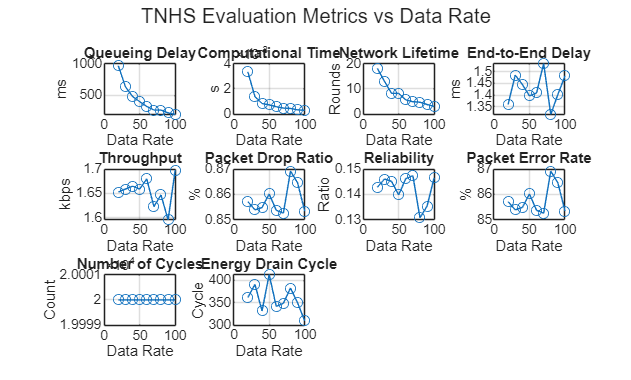

% TNHS Routing Protocol for Implant WBAN - Updated with PER, Cycles, Energy Drain Cycle
clc; clear;

%% Parameters
areaSize = 250;                 
numRelays = 7;
numSources = 8;
numSink = 1;
numNodes = numRelays + numSources + numSink;  
range = 50;                     
initialEnergy = 7;             
energyThreshold = 0.2 * initialEnergy;
normalTemp = 37;               
tempThreshold = 39;            
criticalThreshold = 40;        
frequency = 2.4e9;             
wavelength = 0.138;            
packetSize = 3000 / 8;         
dataRates = 20:10:100;         
simTime = 1000;                
queueDelayBase = 5; queueVar = 10;

%% Initialize Nodes
roles = [repmat("Relay", 1, numRelays), repmat("Source", 1, numSources), "Sink"];
positions = rand(numNodes, 2) * areaSize;
energyOriginal = initialEnergy * ones(numNodes, 1);
sinkID = numNodes;

%% Load Sensor Data
sensorData = readmatrix('DATA.csv');
if size(sensorData,2) ~= numSources
    error('Expected 8 columns of sensor data for 8 source nodes.');
end

numCycles = size(sensorData,1); % New metric

%% Metrics Initialization
energyPerSource = zeros(length(dataRates), numSources);
metrics = zeros(length(dataRates), 10); 
% QueueDelay, Time, Lifetime, E2EDelay, Throughput, DropRatio, Reliability, PER, Cycles, EnergyDrainCycle

%% Start Simulation
for drIdx = 1:length(dataRates)
    dataRate = dataRates(drIdx);
    energy = energyOriginal;
    nodeDead = false(numNodes, 1);
    energyDrainCycle = 0;

    totalQueueDelay = 0;
    totalE2EDelay = zeros(numCycles, 1);
    networkLifetime = 0;
    tStart = tic;

    totalPacketsSent = 0;
    totalPacketsReceived = 0;
    totalPacketsDropped = 0;

    for t = 1:numCycles
        roundE2EDelay = 0; validCount = 0;

        for s = 1:numSources
            srcID = numRelays + s;
            if nodeDead(srcID), continue; end

            tempValue = sensorData(t, 3); 

            isCritical = (s == 3 && tempValue >= criticalThreshold);
            totalPacketsSent = totalPacketsSent + 1;

            if isCritical
                distToSink = norm(positions(srcID,:) - positions(sinkID,:));
                delay = rand() * 100 + distToSink * 0.1;
                roundE2EDelay = roundE2EDelay + delay;
                energy(srcID) = energy(srcID) - 0.1;

                if energy(srcID) < energyThreshold
                    nodeDead(srcID) = true;
                    totalPacketsDropped = totalPacketsDropped + 1;
                else
                    totalPacketsReceived = totalPacketsReceived + 1;
                end
            else
                dists = vecnorm(positions - positions(srcID,:), 2, 2);
                eligibleRelays = find(dists <= range & roles == "Relay" & ~nodeDead);

                if isempty(eligibleRelays)
                    totalPacketsDropped = totalPacketsDropped + 1;
                    continue;
                end

                relayID = eligibleRelays(randi(length(eligibleRelays)));

                if relayID <= numNodes && srcID <= numNodes
                    delay = rand() * queueVar + queueDelayBase;
                    roundE2EDelay = roundE2EDelay + delay;

                    energy(srcID) = energy(srcID) - 0.05;
                    energy(relayID) = energy(relayID) - 0.05;

                    if energy(srcID) < energyThreshold, nodeDead(srcID) = true; end
                    if energy(relayID) < energyThreshold, nodeDead(relayID) = true; end

                    if nodeDead(srcID) || nodeDead(relayID)
                        totalPacketsDropped = totalPacketsDropped + 1;
                    else
                        totalPacketsReceived = totalPacketsReceived + 1;
                    end
                else
                    totalPacketsDropped = totalPacketsDropped + 1;
                end
            end

            % Track first drain round
            if energyDrainCycle == 0 && any(energy(numRelays+1:numRelays+numSources) < energyThreshold)
                energyDrainCycle = t;
            end

            if networkLifetime == 0 && any(energy < energyThreshold)
                networkLifetime = t;
            end

            totalQueueDelay = totalQueueDelay + queueDelayBase;
            validCount = validCount + 1;
        end

        if validCount > 0
            totalE2EDelay(t) = roundE2EDelay / validCount;
        else
            totalE2EDelay(t) = NaN;
        end
    end

    % Compute metrics
    tComp = toc(tStart) / dataRate;
    throughput = (totalPacketsReceived * packetSize * 8) / (simTime * 1000);
    dropRatio = totalPacketsDropped / totalPacketsSent;
    reliability = totalPacketsReceived / totalPacketsSent;
    PER = dropRatio * 100;

    metrics(drIdx,:) = [
        totalQueueDelay / dataRate, ...
        tComp, ...
        networkLifetime / dataRate, ...
        mean(totalE2EDelay(~isnan(totalE2EDelay))), ...
        throughput, ...
        dropRatio, ...
        reliability, ...
        PER, ...
        numCycles, ...
        energyDrainCycle
    ];

    for s = 1:numSources
        srcID = numRelays + s;
        if srcID <= length(energy)
            energyPerSource(drIdx,s) = initialEnergy - energy(srcID);
        end
    end
end

%% Save Metrics
writematrix([dataRates(:), metrics(:,1)], 'Queueing_Delay_TNHS.csv');
writematrix([dataRates(:), metrics(:,2)], 'Computational_Time_TNHS.csv');
writematrix([dataRates(:), metrics(:,3)], 'Network_Lifetime_TNHS.csv');
writematrix([dataRates(:), metrics(:,4)], 'End_to_End_Delay_TNHS.csv');
writematrix([dataRates(:), metrics(:,5)], 'Throughput_TNHS.csv');
writematrix([dataRates(:), metrics(:,6)], 'Packet_Drop_Ratio_TNHS.csv');
writematrix([dataRates(:), metrics(:,7)], 'Reliability_TNHS.csv');
writematrix([dataRates(:), metrics(:,8)], 'Packet_Error_Rate_TNHS.csv');
writematrix([dataRates(:), metrics(:,9)], 'Number_of_Cycles_TNHS.csv');
writematrix([dataRates(:), metrics(:,10)], 'Energy_Drain_Cycle_TNHS.csv');
writematrix(energyPerSource, 'Energy_Source_Node_TNHS.csv');

%% Plot Results
figure;
subplot(3,4,1); plot(dataRates, metrics(:,1), '-o'); title('Queueing Delay'); xlabel('Data Rate'); ylabel('ms'); grid on;
subplot(3,4,2); plot(dataRates, metrics(:,2), '-o'); title('Computational Time'); xlabel('Data Rate'); ylabel('s'); grid on;
subplot(3,4,3); plot(dataRates, metrics(:,3), '-o'); title('Network Lifetime'); xlabel('Data Rate'); ylabel('Rounds'); grid on;
subplot(3,4,4); plot(dataRates, metrics(:,4), '-o'); title('End-to-End Delay'); xlabel('Data Rate'); ylabel('ms'); grid on;
subplot(3,4,5); plot(dataRates, metrics(:,5), '-o'); title('Throughput'); xlabel('Data Rate'); ylabel('kbps'); grid on;
subplot(3,4,6); plot(dataRates, metrics(:,6), '-o'); title('Packet Drop Ratio'); xlabel('Data Rate'); ylabel('%'); grid on;
subplot(3,4,7); plot(dataRates, metrics(:,7), '-o'); title('Reliability'); xlabel('Data Rate'); ylabel('Ratio'); grid on;
subplot(3,4,8); plot(dataRates, metrics(:,8), '-o'); title('Packet Error Rate'); xlabel('Data Rate'); ylabel('%'); grid on;
subplot(3,4,9); plot(dataRates, metrics(:,9), '-o'); title('Number of Cycles'); xlabel('Data Rate'); ylabel('Count'); grid on;
subplot(3,4,10); plot(dataRates, metrics(:,10), '-o'); title('Energy Drain Cycle'); xlabel('Data Rate'); ylabel('Cycle'); grid on;
sgtitle('TNHS Evaluation Metrics vs Data Rate');

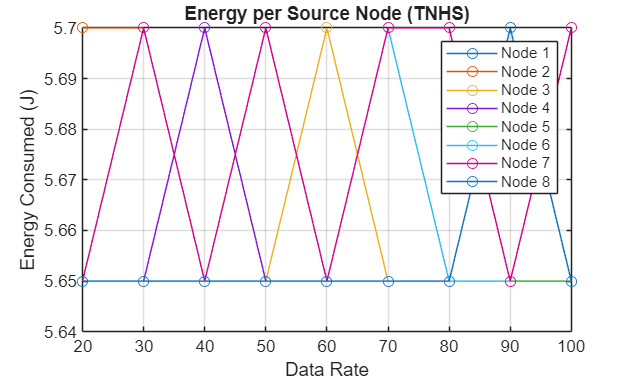


figure;
for s = 1:numSources
    plot(dataRates, energyPerSource(:,s), '-o', 'DisplayName', ['Node ' num2str(s)]); hold on;
end
xlabel('Data Rate'); ylabel('Energy Consumed (J)');
title('Energy per Source Node (TNHS)'); grid on; legend show;